clear

r = @(x) 100*(x(2)-x(1)^2)^2 + (1-x(1))^2;

Nvar = 2;
NPontosIniciais = 3;
x_values=[-11;-11]; y_values=[7;7];

% PontosIniciais = getNPontosIniciais(NPontosIniciais, Nvar,x_values,y_values)
% PontosIniciais = [2.0,-5.0;-5.0,2.0]
PontosIniciais = [-5.0,-5.0,-5.0;2.0,1.0,0.0]

PontosIniciais =     -5    -5    -5
     2     1     0


lambda = 0.00005;
Nmax = randi([35,50])

Nmax = 38

errodf = 15e-2

errodf = 0.1500

[Lista, LNit, Lopt, dffinal] = steepest_descent_static(r, Nmax, errodf, PontosIniciais, x_values, y_values, lambda);

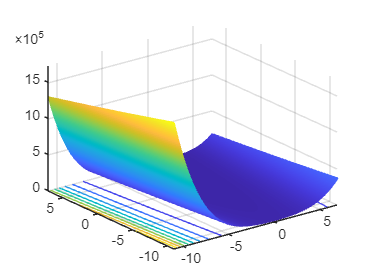

close all

nivelGraficos(r,x_values(1),y_values(1),x_values(2),y_values(2))

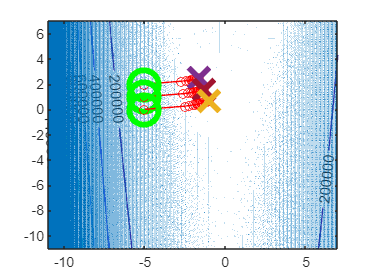


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off